# 802.11ax Uplink OFDMA Multinode System-Level Simulation

This example shows how to simulate a WLAN multinode uplink (UL) orthogonal frequency-division multiple access (OFDMA) network consisting of an IEEE® 802.11ax™ [1] access point (AP) and four stations (STAs) by using WLAN Toolbox™ and the Communications Toolbox™ Wireless Network Simulation Library.

Using this example, you can:

- Create and configure a WLAN multinode scenario consisting of an AP and four STAs.

- Configure and add On-Off application traffic from the STAs to the AP.

- Add the channel model, and simulate UL OFDMA communication from the STAs initiated by the AP.

- Capture the application layer (APP), medium access control layer (MAC) and physical layer (PHY) statistics for each node.

The simulation results show performance metrics such as throughput, packet latency, and packet loss captured at each node.

Additionally, you can further explore the example by performing these tasks.

- Throughput Comparison of OFDM and UL OFDMA

- Faster Execution Using Parallel Simulation Runs

## UL OFDMA Multinode 802.11ax Scenario

This example creates, configures, and simulates this 802.11ax system-level scenario, consisting of one AP and four associated STAs.

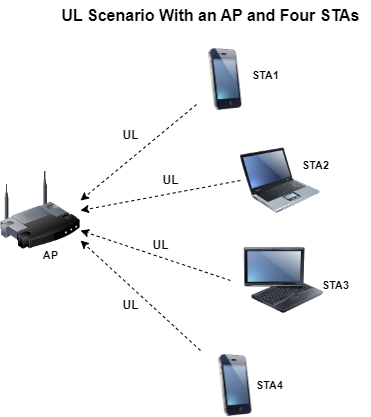

In this figure:

- The AP transmits a basic trigger frame to solicit UL data frames from all the STAs simultaneously.

- Each STA responds with UL data frames.

- The AP transmits a multi-STA block ack frame in response to UL data frames.

## Check for Support Package Installation

Check if the Communications Toolbox™ Wireless Network Simulation Library support package is installed. If the support package is not installed, MATLAB® returns an error with a link to download and install the support package.

wirelessnetworkSupportPackageCheck

## Configure Simulation Parameters

Set the seed for the random number generator to `1`. The seed value controls the pattern of random number generation. The random number generated by the seed value impacts several processes within the simulation, including backoff counter selection at the MAC layer and predicting packet reception success at the PHY. To improve the accuracy of your simulation results, change the seed value, run the simulation again, and average the results over multiple simulations.

rng(1,"combRecursive")

Specify the simulation time in seconds. To visualize a live state transition plot for all of the nodes, set the `enablePacketVisualization` variable to `true`. To view the node performance visualization, set the `enableNodePerformancePlot` variable to `true`.

simulationTime = 0.1;
enablePacketVisualization = true;
enableNodePerformancePlot = true;

This example uses abstracted MAC and PHY at each WLAN node because WLAN node supports UL OFDMA for only abstracted MAC and PHY. To enable abstracted PHY at each node, set the `PHYAbstractionMethod` variable to either `tgax-evaluation-methodology` or `tgax-mac-calibration`. For more information about abstracted MAC and PHY, see the [Get Started with WLAN System-Level Simulation in MATLAB](docid:wlan_ug#example-WLANSystemLevelSimulationExample) example.

PHYAbstractionMethod = "tgax-evaluation-methodology";

## Configure WLAN Scenario

Initialize the wireless network simulator by creating a [`wirelessNetworkSimulator`](docid:comm_ref#mw_d18d4a33-0cf8-49d9-abb5-a4cfa0de673d) object.

networkSimulator = wirelessNetworkSimulator.init;

### Nodes

Specify the number of nodes in the network. The example scenario consists of one AP and four associated STAs.

numNodes = 5;
numSTAs = numNodes-1;

Specify the positions of the AP and STA nodes. The `apPosition` and `staPositions` vectors specify the Cartesian coordinates of the AP and STAs, respectively, in the $x$-, $y$-, and $z$- axes. Units are in meters.

apPosition = [0 0 0];
staPositions = [((30/numSTAs).*(1:numSTAs))' ((30/numSTAs).*(numSTAs:-1:1))' zeros(numSTAs,1)];

To model the scenario, create an AP and four STAs using [`wlanNode`](docid:wlan_ref#mw_object_wlanNode) and [`wlanDeviceConfig`](docid:wlan_ref#mw_object_wlanDeviceConfig) objects. Create two WLAN device configuration objects, one for the AP and the other for the STAs. You can use the same device configuration object to configure all the STAs.

To configure an AP and a STA, set the `Mode` property of one `wlanDeviceConfig` object to `"AP"` and the other to `"STA"`. Specify the configuration parameters for the AP and STAs by using the `wlanDeviceConfig` object. To enable the UL OFDMA functionality, set the `EnableUplinkOFDMA` property of the AP device configuration object to `true`.

The example simulates this UL OFDMA frame exchange sequence — Basic trigger frames from the AP followed by UL multiuser (MU) frames from multiple scheduled STAs, and then a multi-STA block ack frame from the AP.

Optionally, you can enable the MU request-to-send (RTS)/clear-to-send (CTS) exchanges in the sequence by specifying the `DisableRTS` property of the `wlanDeviceConfig` object for the AP as `false`.

For information about how to run a DL OFDMA multinode simulation, see the [802.11ax Downlink OFDMA Multinode System-Level Simulation](docid:wlan_ug#mw_910b8433-a9d6-4423-9aa8-dd5e6f477286) example.

The AP performs these steps in the round-robin scheduling strategy and selects the STAs for each UL MU transmission:

- Schedule the STAs with nonzero queue sizes.

- If the number of users does not reach the maximum that can be scheduled for a given bandwidth in the first step, the AP selects the STAs with unknown queue sizes.

- The AP does not schedule the STAs with zero queue sizes.

The AP uses fixed assignment of resource units (RUs) for a given number of users and amount of bandwidth. The AP allocates equal-sized RUs to the scheduled STAs. For a given number of scheduled STAs, if the AP cannot perform equal-sized RU allocation, it assigns the RUs so as to minimize the difference between RU sizes.

accessPointCfg = wlanDeviceConfig(Mode="AP", ...   % AP device configuration
    TransmissionFormat="HE-MU-OFDMA", ...
    EnableUplinkOFDMA=true, ...
    DisableRTS=true, ...
    MPDUAggregationLimit=1, ...
    MCS=11, ...
    TransmitPower=20);
stationCfg = wlanDeviceConfig(Mode="STA", ...      % STAs device configuration
    DisableRTS=true, ...
    MPDUAggregationLimit=1, ...
    MCS=11, ...
    TransmitPower=20);

To create one AP and four STA nodes from the specified configuration, use `wlanNode` objects. Specify the node names, node positions, and device configuration objects. To create multiple nodes at a time, specify multiple node positions to the same `wlanNode` object. Specify the PHY abstraction method used by the AP and STAs. To indicate that the WLAN nodes abstract the MAC frames, enable the `MACFrameAbstraction` property.

accessPoint = wlanNode(Name="AP", ...
    Position=apPosition, ...
    DeviceConfig=accessPointCfg,...
    PHYAbstractionMethod=PHYAbstractionMethod, ...
    MACFrameAbstraction=true);

stations = wlanNode(Name="STA"+(1:numSTAs), ...
    Position=staPositions, ...
    DeviceConfig=stationCfg, ...
    PHYAbstractionMethod=PHYAbstractionMethod, ...
    MACFrameAbstraction=true);

nodes = [accessPoint stations];

To ensure all the nodes are configured properly, use the [`hCheckWLANNodesConfiguration`](matlab:edit("hCheckWLANNodesConfiguration.m")) helper function.

hCheckWLANNodesConfiguration(nodes)

### Association

Associate all the STAs to the AP by using the [`associateStations`](docid:wlan_ref#mw_function_associateStations) object function of the `wlanNode` object.

associateStations(accessPoint,stations)

### Application Traffic

Create four [`networkTrafficOnOff`](docid:comm_ref#mw_0b2cd92a-350a-4264-9283-db5da34bd041) objects, one for each AP-STA pair, to generate an On-Off application traffic pattern. Configure the On-Off application traffic by specifying the application data rate, packet size, On time, and Off time. The number of objects created equals the number of AP-STA pairs that have uplink traffic exchange in the example. Add application traffic from each STA node to the AP node by using the [`addTrafficSource`](docid:wlan_ref#mw_function_wlanaddTrafficSource) object function.

for staIdx=1:numNodes-1
    trafficSource(staIdx) = networkTrafficOnOff(DataRate=20000,PacketSize=100,OnTime=inf,OffTime=0);         %#ok<SAGROW>
    addTrafficSource(stations(staIdx),trafficSource(staIdx),DestinationNode=accessPoint,AccessCategory=0)
end

### Wireless Channel

To add a random TGax fading channel between each node, this example uses the [`hSLSTGaxMultiFrequencySystemChannel`](matlab:edit("hSLSTGaxMultiFrequencySystemChannel.m")) helper function. When you model a fading channel, the probability of packet transmission success depends on these major factors.

- Quality of the channel between a STA and an AP for the selected RU

- Modulation and coding scheme (MCS)

In this example, the RU allocation strategy does not consider the quality of the channel between each STA and the AP. Therefore, if the channel quality between a STA and an AP is poor and the selected MCS is high, you are likely to experience packet loss.

Add the channel model to the wireless network simulator by using the [`addChannelModel`](docid:comm_ref#mw_17054773-3d39-4e39-8566-5fac05380a1e) object function of the `wirelessNetworkSimulator` object.

channel = hSLSTGaxMultiFrequencySystemChannel(nodes);
addChannelModel(networkSimulator,channel.ChannelFcn)

## Simulation and Results

Add the nodes to the wireless network simulator.

addNodes(networkSimulator,nodes)

To view the state transition plot, use the [`hPlotPacketTransitions`](matlab:edit("hPlotPacketTransitions.m")) helper object. To disable the packet communication over frequency subplot, set the `FrequencyPlotFlag` property of `hPlotPacketTransitions` helper object to `false`.

if enablePacketVisualization
    packetVisObj = hPlotPacketTransitions(nodes,simulationTime,FrequencyPlotFlag=false);
end

To view the node performance visualization, use the [`hVisualizePerformance`](matlab:edit("hVisualizePerformance.m")) helper object.

if enableNodePerformancePlot
    performancePlotObj = hVisualizePerformance(nodes,simulationTime);
end

Run the network simulation for the specified simulation time. The runtime visualization shows the time spent by the AP and the STAs in Idle, Contention, Transmission, and Reception states.

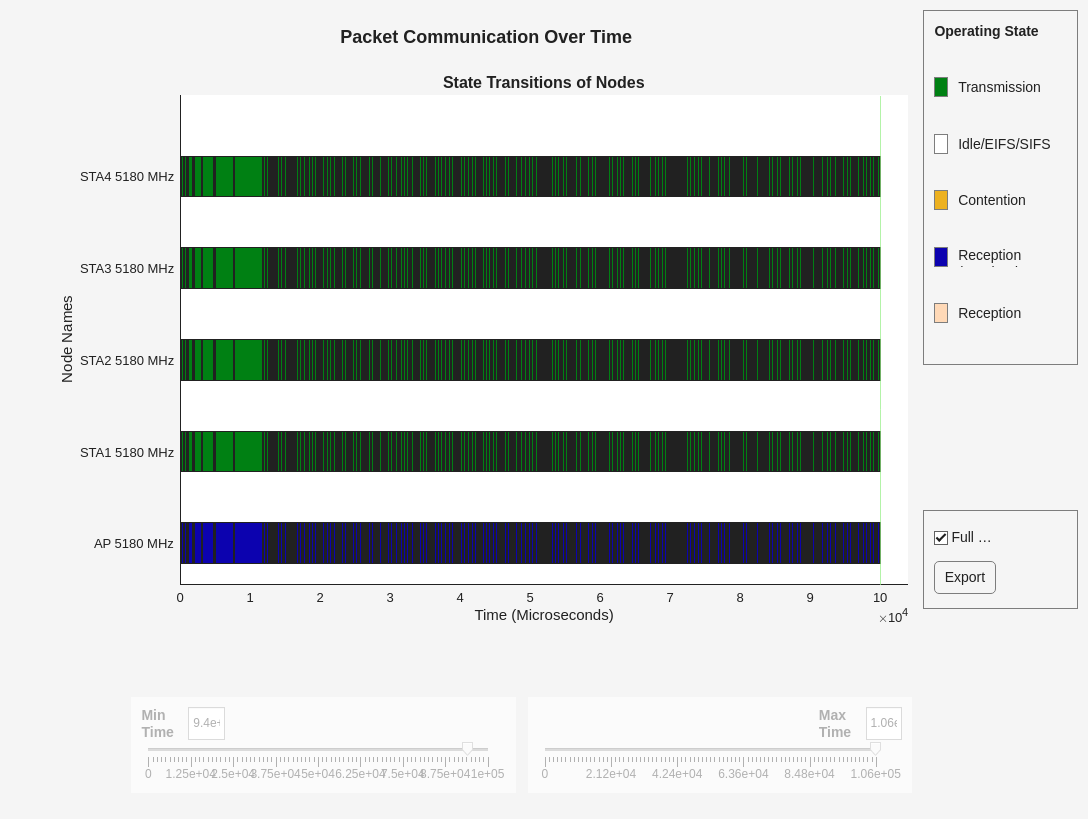

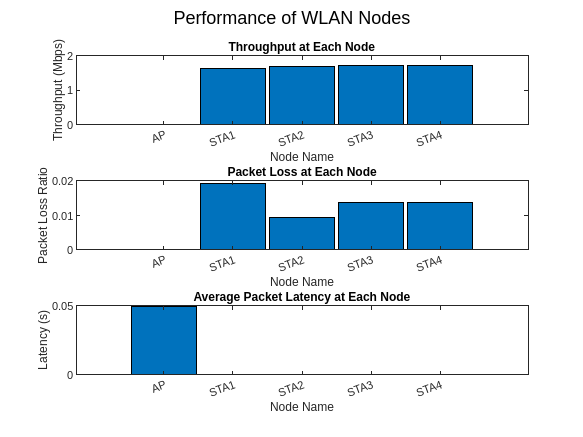

run(networkSimulator,simulationTime)

The preceding figure displays these simulation plots.

- Throughput (in Mbps) at each transmitter (STA).

- Packet loss ratio — Ratio of unsuccessful data transmissions to the total data transmissions at each transmitter (STA).

- Average packet latency — Average latency incurred by the receiver (AP) to receive uplink traffic from the STAs.

Retrieve the APP, MAC, and PHY statistics at each node by using the [`statistics`](docid:wlan_ref#mw_function_wlanstatistics) object function of the `wlanNode` object. For more information about the statistics, see [WLAN System-Level Simulation Statistics](docid:wlan_ug#mw_cbfaee30-7467-406f-84ad-20230f9245e2).

stats = statistics(nodes);

## Further Exploration

You can use this example to further explore these capabilities.

### Throughput Comparison of OFDM and UL OFDMA

Generate the throughput results of these OFDM and UL OFDMA transmission scenarios by using the [`hCompareOFDMvsULOFDMAThroughputs`](matlab:edit("hCompareOFDMvsULOFDMAThroughputs.m")) helper function.

- An AP serving a maximum of 135 STAs with an OFDM configuration.

- An AP serving a maximum of 135 STAs in a UL OFDMA configuration.

Plot the throughput results as a function of the number of STAs for the OFDM and UL OFDMA configurations. By default, the `hCompareOFDMvsULOFDMAThroughputs` helper function plots the stored throughput values of OFDM and UL OFDMA transmissions. If you set `plotStoredThroughputValues` to false, the example simulates the preceding scenarios again and reproduces the results.

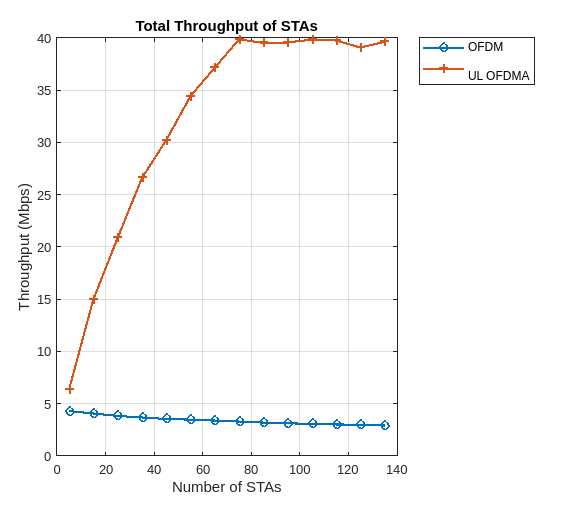

plotStoredThroughputValues = true;
hCompareOFDMvsULOFDMAThroughputs(plotStoredThroughputValues)

The preceding plot shows the throughput comparison of OFDM and UL OFDMA. Note that, because of the simultaneous transmissions from multiple users, the throughput obtained by using UL OFDMA transmission is greater than the throughput obtained by using OFDM transmission.

### Faster Execution Using Parallel Simulation Runs

If you want to run multiple simulations, you can speed up the simulations by enabling parallel computing using the [`parfor`](docid:matlab_ref#f71-813245) loop. The `parfor` loop is an alternative to the [`for`](docid:matlab_ref#buhafgy-1) loop that enables you to execute multiple simulation runs in parallel, thereby reducing the total execution time. To use `parfor`, you must have a license for [Parallel Computing Toolbox](docid:distcomp_doccenter#index)™. For more information about how to run multiple simulations using a `parfor` loop, see the [`hCompareOFDMvsULOFDMAThroughputs`](matlab:edit("hCompareOFDMvsULOFDMAThroughputs.m")) helper function.

## Appendix

The example uses these helpers:

- [`hCheckWLANNodesConfiguration`](matlab:edit("hCheckWLANNodesConfiguration.m")) — Check if the node parameters are configured correctly

- [`hSLSTGaxMultiFrequencySystemChannel`](matlab:edit("hSLSTGaxMultiFrequencySystemChannel.m")) — Return a system channel object, and set the path loss model

- [`hSLSTGaxAbstractSystemChannel`](matlab:edit("hSLSTGaxAbstractSystemChannel.m")) — Return a channel object for an abstracted PHY layer

- [`hSLSTGaxSystemChannel`](matlab:edit("hSLSTGaxSystemChannel.m")) — Return a channel object for a full PHY layer

- [`hSLSTGaxSystemChannelBase`](matlab:edit("hSLSTGaxSystemChannelBase.m")) — Return the base channel object

- [`hCompareOFDMvsULOFDMAThroughputs`](matlab:edit("hCompareOFDMvsULOFDMAThroughputs.m")) — Retrieve throughput results for OFDM and UL OFDMA transmission scenarios

- [`hPlotPacketTransitions`](matlab:edit("hPlotPacketTransitions.m")) — Plot the state transition figure

- [`hVisualizePerformance`](matlab:edit("hVisualizePerformance.m")) — Plot the performance metrics figure

## References

[1] "IEEE Standard for Information Technology--Telecommunications and Information Exchange between Systems Local and Metropolitan Area Networks--Specific Requirements Part 11: Wireless LAN Medium Access Control (MAC) and Physical Layer (PHY) Specifications Amendment 1: Enhancements for High-Efficiency WLAN.” IEEE. [https://doi.org/10.1109/IEEESTD.2021.9442429](https://doi.org/10.1109/IEEESTD.2021.9442429).

[2] "IEEE Standard for Information Technology--Telecommunications and Information Exchange between Systems - Local and Metropolitan Area Networks--Specific Requirements - Part 11: Wireless LAN Medium Access Control (MAC) and Physical Layer (PHY) Specifications.” IEEE. [https://doi.org/10.1109/IEEESTD.2021.9363693](https://doi.org/10.1109/IEEESTD.2021.9363693).

*Copyright 2023 The MathWorks, Inc.*